f= @(x) exp(sin(7.*x));
I= integral(f,0,2);
fprintf("Integral= %.15f",I);

Integral= 2.663219782761539

T= Trapezoid(f,0,2,40);
fprintf("Trapezoid Integral= %.15f",T);

Trapezoid Integral= 2.662302935602287

n = 40*2.^(0:5)';
err = zeros(size(n));
for k = 1:length(n)
    T = Trapezoid(f,0,2,n(k));
    err(k) = abs(I - T);
end
table(n,err)

ans = 6×2 table
     n         err    
    ____    __________

      40    0.00091685
      80    0.00023006
     160    5.7568e-05
     320    1.4395e-05
     640     3.599e-06
    1280    8.9975e-07


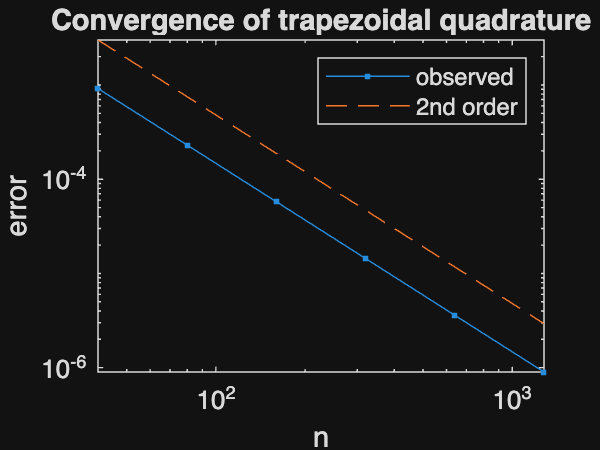

loglog(n,err,'.-')
hold on, loglog(n,3e-3*(n/n(1)).^(-2),'--')
xlabel('n'), ylabel('error'), axis tight
title('Convergence of trapezoidal quadrature')
legend('observed','2nd order')

%Composite Trapezoid rule

function T= Trapezoid(f,a,b,n)
    h=(b-a)/n;
    x=a + h.*(0:n);
    y=f(x);
    T=h*(sum(y(2:n))+ 0.5*(y(1)+y(n+1)));

end
